% 参数设置
N = 9;  % 无人机数量（不包括中心无人机）
dt = 0.1;  % 时间步长
prediction_horizon = 20;  % 预测时域长度
lambda_r = 0.1;  % 径向控制输入权重
lambda_theta = 0.1;  % 角度控制输入权重
max_iter = 100;  % 最大迭代次数

% 初始位置（极坐标）
positions = [
    100, 0;
     98, 40.10;
    112, 80.21;
    105, 119.75;
     98, 159.86;
    112, 199.96;
    105, 240.07;
     98, 280.17;
    112, 320.28
];

% 理想位置（圆形编队）
ideal_positions = [
    100, 0;
    100, 40;
    100, 80;
    100, 120;
    100, 160;
    100, 200;
    100, 240;
    100, 280;
    100, 320
];

% 理想位置
ideal_theta = linspace(0, 320, N);  % 理想角度位置
ideal_radius = 100;  % 理想半径

% 系统模型
A = eye(2);  % 状态转移矩阵，单位矩阵，表示无状态变化
B = eye(2) * dt;  % 控制输入矩阵，乘以时间步长

% 修复目标函数以确保它返回一个标量值
function cost = objective(u, x0, x_ideal, A, B, N, dt, lambda_r, lambda_theta)
    cost = 0;  % 初始化成本
    x = x0;  % 初始状态
    for k = 1:N
        u_k = u(2*k-1:2*k);  % 获取第k步的控制输入
        x = A * x + B * u_k;  % 计算下一个状态
        x = x(1);
        % 确保成本是累加的标量值
        cost = cost + sum((x - x_ideal).^2) + lambda_r * u_k(1)^2 + lambda_theta * u_k(2)^2;
    end
end

% 约束条件
lb = -ones(2 * prediction_horizon, 1);  % 控制输入的下界
ub = ones(2 * prediction_horizon, 1);  % 控制输入的上界

% 计算方向信息
function angles = calculate_angles(positions, i, selected_indices)
    % 计算无人机i接收到的方向信息（夹角）
    angles = zeros(1, numel(selected_indices));
    for j = 2:numel(selected_indices)
        delta_x = positions(selected_indices(j), 1) * cosd(positions(selected_indices(j), 2)) - positions(i, 1) * cosd(positions(i, 2));
        delta_y = positions(selected_indices(j), 1) * sind(positions(selected_indices(j), 2)) - positions(i, 1) * sind(positions(i, 2));
        delta_x0 = 0 - positions(i, 1) * cosd(positions(i, 2));
        delta_y0 = -positions(i, 1) * sind(positions(i, 2));
        % 计算角度
        angles(j) = [delta_x, delta_y] * [delta_x0, delta_y0]' / (norm([delta_x0, delta_y0]) * norm([delta_x, delta_y]));
    end
end

% 计算位置误差
function position = calculate_position_from_angles(selected_positions, angles)
    % 基于方向信息计算位置
    position = four_a2a3toR(selected_positions(2, 1), selected_positions(2, 2), selected_positions(3, 1), selected_positions(3, 2), acos(angles(2)), acos(angles(3)));
end

% MPC控制
for t = 1:max_iter
    % 随机选择最多3架无人机发送信号
    selected_indices = randsample(N, 2);
    selected_indices = [1, selected_indices'];  % 加上中心无人机FY00
    
    for i = 1:N
        if ismember(i, selected_indices)
            continue;  % 发射信号的无人机不调整位置
        end
        
        % 计算方向信息
        angles = calculate_angles(positions, i, selected_indices);
        
        % 计算当前位置
        fy00_pos = [0, 0];  % 中心无人机位置
        selected_positions = positions(selected_indices, :);
        current_position = calculate_position_from_angles(selected_positions, angles);
        
        % 目标函数优化
        u0 = zeros(2 * prediction_horizon, 1);  % 初始控制输入
        x0 = current_position';  % 当前状态
        x_ideal = ideal_positions(i, :)';  % 理想状态
        options = optimoptions('fmincon', 'Display', 'off');  % 优化选项
        % 优化控制输入
        u_opt = fmincon(@(u) objective(u, x0, x_ideal, A, B, prediction_horizon, dt, lambda_r, lambda_theta), u0, [], [], [], [], lb, ub, [], options);
        
        % 应用控制输入
        positions(i, 1) = positions(i, 1) + u_opt(1) * dt;
        positions(i, 2) = positions(i, 2) + u_opt(2) * dt;
    end
    
    % 打印当前时刻的位置
    fprintf('时间步 %d，位置：\n', t);
    disp(positions);
end


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3                9302                        1.11e+03              1
     1          6             9096.97              1              475              1
     2          9             8837.15            2.5              179            2.5
     3         12             8249.18           6.25             46.1           6.25
     4         15             6874.64         15.625              240           15.6
     5         18             3954.83        39.0625              310           39.1
     6         21             143.433        97.6563              126           97.7
     7         24         0.000815576        22.7687            0.574            244
     8         27         1.54397e-18      0.0536207         1.89e-08            244



时间步 1，位置：


  100.0000         0
   98.1000   40.1000
  112.1000   80.2100
  105.1000  119.7500
   98.0000  159.8600
  112.0000  199.9600
  105.1000  240.0700
   98.1000  280.1700
  112.1000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             3700.88                             187              1
     1          6             3557.04              1              152              1
     2          9             3213.01            2.5              190            2.5
     3         12             2409.09           6.25              325           6.25
     4         15             837.686         15.625              434           15.6
     5         18             1.51459        21.9851             7.05           39.1
     6         21         3.59709e-09       0.906664          0.00077             55
     7         24         1.84985e-25    4.38505e-05         2.86e-11             55

方程已解。

fsolve 已完成，因为按照

时间步 2，位置：


  100.0000         0
   98.0000   40.1000
  112.1000   80.2100
  105.2000  119.7500
   98.1000  159.8600
  112.1000  199.9600
  105.0000  240.0700
   98.2000  280.1700
  112.2000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             8515.59                        3.05e+03              1
     1          6             8.90378              1             68.4              1
     2          9             6.60775            2.5              1.3            2.5
     3         12              2.7242           6.25             9.66           6.25
     4         15           0.0266811        11.2409             23.3           15.6
     5         18          1.4583e-12       0.095932         0.000172           28.1
     6         21         3.38406e-25    9.77413e-07         8.32e-11           28.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 3，位置：


  100.0000         0
   98.1000   40.1000
  112.0000   80.2100
  105.2000  119.7500
   98.2000  159.8600
  112.2000  199.9600
  104.9000  240.0700
   98.3000  280.1700
  112.3000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             14077.2                             412              1
     1          6             13922.7              1              598              1
     2          9               13521            2.5              907            2.5
     3         12             12435.5           6.25          1.4e+03           6.25
     4         15             9562.61         15.625         1.94e+03           15.6
     5         18             3420.14        39.0625         1.72e+03           39.1
     6         21             24.2413        58.1233             38.2           97.7
     7         24         5.62647e-05        4.59347            0.249            145
     8         27         2.76968e-21     0.00676267         1.03e-09            145



时间步 4，位置：


  100.0000         0
   98.2000   40.1000
  112.0000   80.2100
  105.3000  119.7500
   98.3000  159.8600
  112.3000  199.9600
  105.0000  240.0700
   98.3000  280.1700
  112.4000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12587.9                         5.8e+03              1
     1          6             33.9225              1              752              1
     2          9             2.25795            2.5             6.11            2.5
     3         12         1.20296e-05        3.36719            0.432           6.25
     4         15         6.00831e-23     0.00407415         8.21e-10           8.42

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 5，位置：


  100.0000         0
   98.3000   40.1000
  112.1000   80.2100
  105.3000  119.7500
   98.4000  159.8600
  112.4000  199.9600
  105.0000  240.0700
   98.4000  280.1700
  112.5000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             6053.69                        6.38e+03              1
     1          6             1259.33              1              895              1
     2          9             1055.77            2.5              103            2.5
     3         12             723.839           6.25             28.4           6.25
     4         15             165.343         15.625             34.6           15.6
     5         18          0.00341361         14.238             2.22           39.1
     6         21         2.79721e-16      0.0613731         7.17e-07           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 6，位置：


  100.0000         0
   98.2000   40.1000
  112.0000   80.2100
  105.4000  119.7500
   98.5000  159.8600
  112.4000  199.9600
  105.1000  240.0700
   98.5000  280.1700
  112.6000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             14123.9                             395              1
     1          6             13972.8              1              580              1
     2          9             13576.4            2.5              892            2.5
     3         12             12496.9           6.25         1.39e+03           6.25
     4         15             9620.86         15.625         1.96e+03           15.6
     5         18             3448.17        39.0625         1.74e+03           39.1
     6         21              24.897        58.3246             40.7           97.7
     7         24         6.01955e-05        4.65192            0.256            146
     8         27         8.56756e-22     0.00699528          2.9e-09            146



时间步 7，位置：


  100.0000         0
   98.3000   40.1000
  112.0000   80.2100
  105.5000  119.7500
   98.6000  159.8600
  112.5000  199.9600
  105.2000  240.0700
   98.5000  280.1700
  112.7000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             5070.91                             817              1
     1          6             4812.59              1              649              1
     2          9             4359.46            2.5              593            2.5
     3         12             3382.57           6.25              633           6.25
     4         15              1457.9         15.625              608           15.6
     5         18             1.29731           30.3             6.16           39.1
     6         21         2.02595e-09       0.898799         8.11e-05           75.8
     7         24          5.5657e-25     3.5569e-05         6.08e-11           75.8

方程已解。

fsolve 已完成，因为按照

时间步 8，位置：


  100.0000         0
   98.2000   40.1000
  112.0000   80.2100
  105.5000  119.7500
   98.7000  159.8600
  112.6000  199.9600
  105.3000  240.0700
   98.4000  280.1700
  112.6000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             11934.2                        4.49e+03              1
     1          6             4243.28              1         4.82e+03              1
     2          9             1491.82            2.5         1.08e+03            2.5
     3         12             999.299           6.25              157           6.25
     4         15             295.517         15.625             21.4           15.6
     5         18          0.00118848        18.6351            0.616           39.1
     6         21         7.14693e-18      0.0368322         6.68e-08           46.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 9，位置：


  100.0000         0
   98.1000   40.1000
  112.1000   80.2100
  105.5000  119.7500
   98.7000  159.8600
  112.7000  199.9600
  105.4000  240.0700
   98.5000  280.1700
  112.5000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             7806.17                        2.97e+03              1
     1          6             6436.37              1         2.19e+03              1
     2          9             5419.17            2.5         1.62e+03            2.5
     3         12             4229.55           6.25         1.22e+03           6.25
     4         15             2293.44         15.625              841           15.6
     5         18             57.7509        39.0625              125           39.1
     6         21         9.38478e-05        7.49402          0.00971           97.7
     7         24         1.28312e-21     0.00966988         2.66e-10           97.7

方程已解。

fsolve 已完成，因为按照

时间步 10，位置：


  100.0000         0
   98.0000   40.1000
  112.1000   80.2100
  105.6000  119.7500
   98.8000  159.8600
  112.8000  199.9600
  105.4000  240.0700
   98.6000  280.1700
  112.6000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             16076.3                        8.67e+03              1
     1          6             333.613              1          2.1e+03              1
     2          9             49.2773            2.5               33            2.5
     3         12         0.000278409           6.25           0.0187           6.25
     4         15         1.86333e-18      0.0149004         1.49e-08           15.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 11，位置：


  100.0000         0
   98.0000   40.1000
  112.2000   80.2100
  105.7000  119.7500
   98.9000  159.8600
  112.7000  199.9600
  105.5000  240.0700
   98.7000  280.1700
  112.7000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10168.9                        9.21e+03              1
     1          6             2032.69              1              363              1
     2          9             1967.71            2.5             43.6            2.5
     3         12             1826.66           6.25             11.1           6.25
     4         15             1497.21         15.625             20.1           15.6
     5         18              816.71        39.0625             8.63           39.1
     6         21             10.7908        97.6562             1.28           97.7
     7         24         2.37763e-09        12.6816          0.00037            244
     8         27         3.17059e-26    0.000187977         6.37e-12            244



时间步 12，位置：


  100.0000         0
   97.9000   40.1000
  112.1000   80.2100
  105.8000  119.7500
   99.0000  159.8600
  112.7000  199.9600
  105.5000  240.0700
   98.8000  280.1700
  112.8000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             11980.4                        4.24e+03              1
     1          6             10320.9              1         1.52e+03              1
     2          9             9660.71            2.5              488            2.5
     3         12             8473.85           6.25             98.4           6.25
     4         15             5879.97         15.625              117           15.6
     5         18              1454.3        39.0625              104           39.1
     6         21          0.00383692        38.5898            0.445           97.7
     7         24          6.6505e-16      0.0624417         4.12e-07           97.7

方程已解。

fsolve 已完成，因为按照

时间步 13，位置：


  100.0000         0
   97.9000   40.1000
  112.2000   80.2100
  105.9000  119.7500
   99.1000  159.8600
  112.7000  199.9600
  105.6000  240.0700
   98.9000  280.1700
  112.9000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             7446.58                        7.04e+03              1
     1          6             4236.76              1             77.4              1
     2          9              3859.8            2.5              122            2.5
     3         12             2992.08           6.25               65           6.25
     4         15             1306.77         15.625              146           15.6
     5         18          0.00100718        30.4086            0.485           39.1
     6         21         1.73755e-15      0.0265223         1.22e-06             76
     7         24         3.15544e-28    3.43313e-08         2.62e-12             76

方程已解。

fsolve 已完成，因为按照

时间步 14，位置：


  100.0000         0
   97.9000   40.1000
  112.2000   80.2100
  106.0000  119.7500
   99.2000  159.8600
  112.8000  199.9600
  105.7000  240.0700
   99.0000  280.1700
  113.0000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             6035.49                        3.17e+03              1
     1          6             4525.86              1         1.42e+03              1
     2          9             4281.56            2.5              322            2.5
     3         12             4083.63           6.25              209           6.25
     4         15             3452.35         15.625              870           15.6
     5         18             1199.44        39.0625            2e+03           39.1
     6         21             630.438        24.5718         1.06e+03           97.7
     7         24           0.0566798        17.9013             5.32           97.7
     8         27          9.5255e-14       0.186876         7.32e-06           97.7
     9         30          3.8976e-25     2.4064e-07         3.7

时间步 15，位置：


  100.0000         0
   97.8000   40.1000
  112.2000   80.2100
  106.1000  119.7500
   99.3000  159.8600
  112.7000  199.9600
  105.8000  240.0700
   99.1000  280.1700
  113.0000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             15973.9                        8.66e+03              1
     1          6             318.637              1         2.05e+03              1
     2          9             45.8444            2.5             31.3            2.5
     3         12         2.26577e-07        6.05097          0.00542           6.25
     4         15         2.60857e-24    0.000424172         8.48e-11           15.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 16，位置：


  100.0000         0
   97.8000   40.1000
  112.3000   80.2100
  106.2000  119.7500
   99.4000  159.8600
  112.6000  199.9600
  105.9000  240.0700
   99.2000  280.1700
  113.1000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             2577.11                        4.06e+03              1
     1          6             1636.11              1              565              1
     2          9             1486.59            2.5              110            2.5
     3         12             1177.17           6.25             89.3           6.25
     4         15             545.478         15.625              156           15.6
     5         18             1.92466        32.5922             91.1           39.1
     6         21         2.71017e-08        1.51486           0.0131           81.5
     7         24          3.0568e-24    0.000163757         9.99e-11           81.5

方程已解。

fsolve 已完成，因为按照

时间步 17，位置：


  100.0000         0
   97.7000   40.1000
  112.3000   80.2100
  106.3000  119.7500
   99.5000  159.8600
  112.6000  199.9600
  106.0000  240.0700
   99.3000  280.1700
  113.0000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             15859.3                        1.19e+04              1
     1          6             1315.73              1         1.95e+03              1
     2          9             984.628            2.5             30.7            2.5
     3         12             638.336           6.25             28.7           6.25
     4         15             99.6361         15.625             9.77           15.6
     5         18         1.66443e-07        10.2056           0.0231           39.1
     6         21         7.95885e-24    0.000386018         4.19e-10           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 18，位置：


  100.0000         0
   97.7000   40.1000
  112.4000   80.2100
  106.4000  119.7500
   99.6000  159.8600
  112.7000  199.9600
  106.1000  240.0700
   99.4000  280.1700
  113.0000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             11364.3                        5.34e+03              1
     1          6             39.0779              1              302              1
     2          9             19.4136            2.5             4.11            2.5
     3         12            0.557646           6.25             2.36           6.25
     4         15         4.62194e-07         1.2786           0.0782           15.6
     5         18         1.74896e-24    0.000690813         1.79e-10           15.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 19，位置：


  100.0000         0
   97.8000   40.1000
  112.3000   80.2100
  106.3000  119.7500
   99.7000  159.8600
  112.8000  199.9600
  106.1000  240.0700
   99.5000  280.1700
  113.1000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             7486.34                        7.09e+03              1
     1          6             1641.52              1         1.02e+03              1
     2          9             1432.35            2.5              127            2.5
     3         12             1100.06           6.25             25.4           6.25
     4         15             458.916         15.625             47.6           15.6
     5         18           0.0324167        28.3762             6.91           39.1
     6         21         2.34478e-13       0.225304         2.34e-05           70.9
     7         24         3.70828e-25    5.90031e-07         8.21e-11           70.9

方程已解。

fsolve 已完成，因为按照

时间步 20，位置：


  100.0000         0
   97.7000   40.1000
  112.4000   80.2100
  106.3000  119.7500
   99.8000  159.8600
  112.8000  199.9600
  106.2000  240.0700
   99.6000  280.1700
  113.2000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             19181.2                        3.01e+03              1
     1          6             14603.5              1         6.42e+03              1
     2          9             4413.59            2.5         4.66e+03            2.5
     3         12             1901.21           6.25         1.26e+03           6.25
     4         15             846.493         15.625              324           15.6
     5         18            0.217029        34.9324              8.4           39.1
     6         21         4.24528e-11       0.543055         0.000188           87.3
     7         24         3.39931e-24    7.44805e-06         2.03e-10           87.3

方程已解。

fsolve 已完成，因为按照

时间步 21，位置：


  100.0000         0
   97.7000   40.1000
  112.3000   80.2100
  106.2000  119.7500
   99.7000  159.8600
  112.9000  199.9600
  106.2000  240.0700
   99.7000  280.1700
  113.3000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             7935.25                        2.96e+03              1
     1          6             6562.49              1         2.22e+03              1
     2          9             5514.57            2.5         1.67e+03            2.5
     3         12             4289.45           6.25         1.26e+03           6.25
     4         15             2320.89         15.625              854           15.6
     5         18             60.7429        39.0625              123           39.1
     6         21         6.71491e-05        7.68306          0.00822           97.7
     7         24         2.39442e-22     0.00816728         7.51e-10           97.7

方程已解。

fsolve 已完成，因为按照

时间步 22，位置：


  100.0000         0
   97.6000   40.1000
  112.3000   80.2100
  106.3000  119.7500
   99.8000  159.8600
  113.0000  199.9600
  106.2000  240.0700
   99.8000  280.1700
  113.4000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             7482.73                        7.12e+03              1
     1          6              1635.7              1         1.01e+03              1
     2          9             1427.85            2.5              125            2.5
     3         12             1095.68           6.25             25.6           6.25
     4         15             455.353         15.625             47.3           15.6
     5         18           0.0313434        28.2255             6.79           39.1
     6         21         2.13595e-13       0.221284         2.24e-05           70.6
     7         24         8.09321e-25    5.62261e-07         1.21e-10           70.6

方程已解。

fsolve 已完成，因为按照

时间步 23，位置：


  100.0000         0
   97.5000   40.1000
  112.4000   80.2100
  106.3000  119.7500
   99.9000  159.8600
  113.0000  199.9600
  106.3000  240.0700
   99.9000  280.1700
  113.5000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             7477.72                        7.12e+03              1
     1          6             1631.13              1         1.01e+03              1
     2          9             1424.09            2.5              124            2.5
     3         12             1092.26           6.25             25.7           6.25
     4         15             452.939         15.625             47.3           15.6
     5         18           0.0310082        28.1387             6.77           39.1
     6         21         2.06536e-13       0.219991          2.2e-05           70.3
     7         24          3.8432e-25    5.53038e-07         8.37e-11           70.3

方程已解。

fsolve 已完成，因为按照

时间步 24，位置：


  100.0000         0
   97.4000   40.1000
  112.5000   80.2100
  106.3000  119.7500
  100.0000  159.8600
  113.0000  199.9600
  106.4000  240.0700
  100.0000  280.1700
  113.6000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             14427.6                        4.19e+03              1
     1          6             7472.92              1         6.18e+03              1
     2          9             1152.15            2.5         1.85e+03            2.5
     3         12             457.609           6.25              236           6.25
     4         15             3.33982         15.625             2.28           15.6
     5         18          4.3209e-09        1.46695         0.000621           39.1
     6         21         7.37112e-27    5.25909e-05         9.28e-12           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 25，位置：


  100.0000         0
   97.4000   40.1000
  112.6000   80.2100
  106.3000  119.7500
  100.1000  159.8600
  113.1000  199.9600
  106.3000  240.0700
  100.1000  280.1700
  113.7000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             2613.23                           4e+03              1
     1          6             1695.46              1              572              1
     2          9              1542.5            2.5              114            2.5
     3         12             1225.57           6.25             92.5           6.25
     4         15             576.064         15.625              161           15.6
     5         18             2.11313        33.3338             94.2           39.1
     6         21         3.46551e-08        1.58496           0.0147           83.3
     7         24         4.33432e-25    0.000184887         5.98e-11           83.3

方程已解。

fsolve 已完成，因为按照

时间步 26，位置：


  100.0000         0
   97.3000   40.1000
  112.6000   80.2100
  106.4000  119.7500
  100.2000  159.8600
  113.1000  199.9600
  106.4000  240.0700
  100.2000  280.1700
  113.6000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             7411.29                        7.73e+03              1
     1          6             3305.89              1              510              1
     2          9             3004.24            2.5             56.6            2.5
     3         12             2343.28           6.25              320           6.25
     4         15             1037.07         15.625             33.3           15.6
     5         18          0.00388091        31.1181             1.12           39.1
     6         21         1.54896e-13      0.0595382          2.1e-05           77.8
     7         24         6.91074e-26    3.53959e-07         3.93e-11           77.8

方程已解。

fsolve 已完成，因为按照

时间步 27，位置：


  100.0000         0
   97.4000   40.1000
  112.6000   80.2100
  106.5000  119.7500
  100.2000  159.8600
  113.2000  199.9600
  106.5000  240.0700
  100.3000  280.1700
  113.7000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             11401.9                         5.4e+03              1
     1          6             41.4967              1              257              1
     2          9             22.1548            2.5             3.75            2.5
     3         12             1.07468           6.25             2.35           6.25
     4         15         1.69095e-06        1.76985            0.151           15.6
     5         18         2.31759e-23     0.00130987         6.23e-10           15.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 28，位置：


  100.0000         0
   97.5000   40.1000
  112.5000   80.2100
  106.4000  119.7500
  100.3000  159.8600
  113.3000  199.9600
  106.5000  240.0700
  100.4000  280.1700
  113.8000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             15789.3                        8.64e+03              1
     1          6             289.707              1         1.96e+03              1
     2          9              39.616            2.5             27.9            2.5
     3         12         1.46993e-07        5.64248          0.00411           6.25
     4         15         6.36905e-24    0.000342829          9.4e-11           14.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 29，位置：


  100.0000         0
   97.5000   40.1000
  112.6000   80.2100
  106.5000  119.7500
  100.4000  159.8600
  113.2000  199.9600
  106.6000  240.0700
  100.5000  280.1700
  113.9000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             11712.3                        4.19e+03              1
     1          6             10114.3              1         1.46e+03              1
     2          9             9477.43            2.5              453            2.5
     3         12             8308.46           6.25             89.4           6.25
     4         15             5750.71         15.625              120           15.6
     5         18             1401.48        39.0625               95           39.1
     6         21          0.00273448        38.0375            0.367           97.7
     7         24         2.42929e-16      0.0529499         2.36e-07           97.7

方程已解。

fsolve 已完成，因为按照

时间步 30，位置：


  100.0000         0
   97.5000   40.1000
  112.7000   80.2100
  106.6000  119.7500
  100.5000  159.8600
  113.2000  199.9600
  106.7000  240.0700
  100.6000  280.1700
  114.0000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             19114.5                        2.95e+03              1
     1          6             14757.6              1         6.29e+03              1
     2          9             4664.31            2.5         4.83e+03            2.5
     3         12             1952.28           6.25         1.33e+03           6.25
     4         15             870.883         15.625              341           15.6
     5         18            0.220102        35.4626             8.05           39.1
     6         21         4.37014e-11       0.548453         0.000185           88.7
     7         24         3.11808e-24    7.58433e-06         1.91e-10           88.7

方程已解。

fsolve 已完成，因为按照

时间步 31，位置：


  100.0000         0
   97.5000   40.1000
  112.6000   80.2100
  106.5000  119.7500
  100.4000  159.8600
  113.3000  199.9600
  106.7000  240.0700
  100.7000  280.1700
  114.1000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             11438.4                        5.41e+03              1
     1          6             40.6438              1              274              1
     2          9             21.1673            2.5             3.88            2.5
     3         12            0.860749           6.25             2.35           6.25
     4         15         1.07289e-06        1.58268             0.12           15.6
     5         18         3.27171e-23      0.0010468         8.15e-10           15.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 32，位置：


  100.0000         0
   97.6000   40.1000
  112.5000   80.2100
  106.4000  119.7500
  100.5000  159.8600
  113.4000  199.9600
  106.7000  240.0700
  100.8000  280.1700
  114.2000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             23751.6                        1.33e+04              1
     1          6             992.803              1         4.29e+03              1
     2          9               33.57            2.5              111            2.5
     3         12             23.2502           6.25             14.4           6.25
     4         15             6.01191         15.625             70.1           15.6
     5         18            0.560951        14.5595             80.4           39.1
     6         21         1.20187e-09       0.753346          0.00374           39.1
     7         24          2.3628e-25    3.08694e-05         5.31e-11           39.1

方程已解。

fsolve 已完成，因为按照

时间步 33，位置：


  100.0000         0
   97.6000   40.1000
  112.6000   80.2100
  106.4327  119.7500
  100.5000  159.8600
  113.5000  199.9600
  106.8000  240.0700
  100.7000  280.1700
  114.3000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             14496.3                         4.2e+03              1
     1          6              7509.6              1          6.2e+03              1
     2          9             1154.85            2.5         1.85e+03            2.5
     3         12             459.428           6.25              236           6.25
     4         15             3.45278         15.625             2.32           15.6
     5         18         4.39756e-09        1.49064         0.000621           39.1
     6         21         5.90598e-25     5.3026e-05         7.85e-11           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 34，位置：


  100.0000         0
   97.6000   40.1000
  112.7000   80.2100
  106.4327  119.7500
  100.6000  159.8600
  113.6000  199.9600
  106.7000  240.0700
  100.8000  280.1700
  114.4000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3              8619.7                        3.18e+03              1
     1          6             6891.67              1         2.63e+03              1
     2          9             5647.05            2.5         1.75e+03            2.5
     3         12             4548.02           6.25              940           6.25
     4         15             2888.33         15.625              298           15.6
     5         18             448.853        39.0625             72.4           39.1
     6         21          0.00386225        25.3713            0.761           97.7
     7         24         1.00183e-16       0.073724         1.55e-07           97.7

方程已解。

fsolve 已完成，因为按照

时间步 35，位置：


  100.0000         0
   97.5000   40.1000
  112.6000   80.2100
  106.5327  119.7500
  100.7000  159.8600
  113.6000  199.9600
  106.8000  240.0700
  100.9000  280.1700
  114.4000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             20792.5                        1.31e+03              1
     1          6             6437.31              1         7.05e+03              1
     2          9              3247.7            2.5             52.6            2.5
     3         12             2625.12           6.25              205           6.25
     4         15             1352.28         15.625               34           15.6
     5         18            0.330421        39.0625            0.534           39.1
     6         21         2.21035e-10       0.619279         0.000633           97.7
     7         24         3.54986e-24     1.5364e-05         2.84e-10           97.7

方程已解。

fsolve 已完成，因为按照

时间步 36，位置：


  100.0000         0
   97.6000   40.1000
  112.7000   80.2100
  106.6327  119.7500
  100.8000  159.8600
  113.7000  199.9600
  106.9000  240.0700
  100.9000  280.1700
  114.4000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             8054.13                        2.95e+03              1
     1          6             6690.36              1         2.24e+03              1
     2          9             5623.95            2.5          1.7e+03            2.5
     3         12              4370.3           6.25          1.3e+03           6.25
     4         15                2368         15.625              874           15.6
     5         18             67.1723        39.0625              126           39.1
     6         21         6.21309e-05        8.07511          0.00879           97.7
     7         24         7.62125e-23     0.00784756         3.34e-10           97.7

方程已解。

fsolve 已完成，因为按照

时间步 37，位置：


  100.0000         0
   97.5000   40.1000
  112.7000   80.2100
  106.7327  119.7500
  100.9000  159.8600
  113.8000  199.9600
  106.9000  240.0700
  101.0000  280.1700
  114.5000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10399.6                        9.42e+03              1
     1          6             2081.96              1              372              1
     2          9             2015.62            2.5             44.7            2.5
     3         12             1871.71           6.25             11.3           6.25
     4         15             1535.49         15.625               21           15.6
     5         18             840.356        39.0625             8.35           39.1
     6         21             12.2101        97.6562             1.21           97.7
     7         24         2.38544e-09        13.3835         0.000353            244
     8         27         3.40328e-24     0.00018683         2.35e-10            244



时间步 38，位置：


  100.0000         0
   97.4000   40.1000
  112.6000   80.2100
  106.8327  119.7500
  101.0000  159.8600
  113.8000  199.9600
  106.9000  240.0700
  101.1000  280.1700
  114.6000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             14857.1                             432              1
     1          6               14694              1              664              1
     2          9             14258.3            2.5         1.04e+03            2.5
     3         12             13069.8           6.25         1.59e+03           6.25
     4         15             9964.08         15.625         2.12e+03           15.6
     5         18             3512.54        39.0625         1.76e+03           39.1
     6         21             20.3985         57.747             38.7           97.7
     7         24         3.20447e-05        4.17114            0.179            144
     8         27         2.26337e-21     0.00507734         3.43e-09            144



时间步 39，位置：


  100.0000         0
   97.5000   40.1000
  112.6000   80.2100
  106.9327  119.7500
  101.1000  159.8600
  113.9000  199.9600
  107.0000  240.0700
  101.1000  280.1700
  114.7000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             22109.5                        5.85e+03              1
     1          6             6740.34              1         5.88e+03              1
     2          9              4013.3            2.5         1.41e+03            2.5
     3         12             3781.77           6.25              509           6.25
     4         15             3503.24         15.625              509           15.6
     5         18              2563.5        39.0625         1.08e+03           39.1
     6         21             396.486        97.6563         1.14e+03           97.7
     7         24             5.46886        15.4822             9.56            244
     8         27         1.15837e-07        3.23431         0.000246            244
     9         30         3.21522e-24    0.000471675         1.0

时间步 40，位置：


  100.0000         0
   97.4000   40.1000
  112.7000   80.2100
  107.0327  119.7500
  101.1000  159.8600
  114.0000  199.9600
  107.1000  240.0700
  101.1000  280.1700
  114.8000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             8632.21                        3.26e+03              1
     1          6             11.6759              1              270              1
     2          9             5.83546            2.5             0.38            2.5
     3         12             2.09327           6.25             9.51           6.25
     4         15           0.0133215        9.35846             16.5           15.6
     5         18         1.85482e-13      0.0721836         6.15e-05           23.4
     6         21         2.40129e-25    3.50147e-07         7.05e-11           23.4

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 41，位置：


  100.0000         0
   97.5000   40.1000
  112.6000   80.2100
  107.0327  119.7500
  101.2000  159.8600
  114.1000  199.9600
  107.0000  240.0700
  101.2000  280.1700
  114.9000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             11297.3                             122              1
     1          6             10599.3              1         2.53e+03              1
     2          9             1518.35            2.5         2.58e+03            2.5
     3         12             1140.03           6.25              294           6.25
     4         15             959.937         15.625              258           15.6
     5         18             450.291        39.0625              834           39.1
     6         19             450.291         53.772              834           97.7
     7         22             182.439         13.443              387           13.4
     8         25             101.699        22.9837             99.1           33.6
     9         28         0.000393727        8.91164            

时间步 42，位置：


  100.0000         0
   97.4000   40.1000
  112.5000   80.2100
  107.0327  119.7500
  101.3000  159.8600
  114.2000  199.9600
  107.1000  240.0700
  101.3000  280.1700
  114.9000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             7581.81                        7.28e+03              1
     1          6             1643.49              1              996              1
     2          9             1437.83            2.5              121            2.5
     3         12             1102.99           6.25             26.4           6.25
     4         15             457.699         15.625             47.4           15.6
     5         18           0.0301479        28.1678             6.73           39.1
     6         21         1.86028e-13       0.216108          2.1e-05           70.4
     7         24         2.01948e-28    5.23039e-07          1.6e-12           70.4

方程已解。

fsolve 已完成，因为按照

时间步 43，位置：


  100.0000         0
   97.3000   40.1000
  112.6000   80.2100
  107.0327  119.7500
  101.4000  159.8600
  114.2000  199.9600
  107.2000  240.0700
  101.4000  280.1700
  115.0000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             14378.5                        4.11e+03              1
     1          6             7807.24              1         6.12e+03              1
     2          9             1277.25            2.5         2.05e+03            2.5
     3         12             492.943           6.25              276           6.25
     4         15             6.72345         15.625             3.23           15.6
     5         18         2.43056e-08        2.08017          0.00159           39.1
     6         21         1.44292e-25    0.000124584         2.52e-11           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 44，位置：


  100.0000         0
   97.3000   40.1000
  112.7000   80.2100
  107.0327  119.7500
  101.5000  159.8600
  114.3000  199.9600
  107.1000  240.0700
  101.5000  280.1700
  115.1000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3               22754                        4.97e+03              1
     1          6             4878.38              1         6.76e+03              1
     2          9             2203.45            2.5              257            2.5
     3         12             1919.98           6.25             21.7           6.25
     4         15             1306.29         15.625              284           15.6
     5         18             278.486        39.0625             33.5           39.1
     6         21          0.00149986        33.5157             1.34           97.7
     7         24         1.07597e-15      0.0752027         1.84e-06           97.7
     8         27         1.11964e-23    6.04188e-08         4.83e-10           97.7



时间步 45，位置：


  100.0000         0
   97.4000   40.1000
  112.8000   80.2100
  107.1327  119.7500
  101.6000  159.8600
  114.4000  199.9600
  107.1000  240.0700
  101.5000  280.1700
  115.2000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             6414.34                         3.3e+03              1
     1          6             4731.54              1         1.56e+03              1
     2          9             4454.21            2.5              370            2.5
     3         12             4257.64           6.25              201           6.25
     4         15             3631.51         15.625              890           15.6
     5         18             1330.53        39.0625         2.09e+03           39.1
     6         21             787.738        26.9169         1.28e+03           97.7
     7         24           0.0981039        19.6867             7.53           97.7
     8         27         4.69545e-13       0.244878         1.75e-05           97.7
     9         30         1.01984e-25     5.3165e-07         2.3

时间步 46，位置：


  100.0000         0
   97.3000   40.1000
  112.8000   80.2100
  107.2327  119.7500
  101.7000  159.8600
  114.3000  199.9600
  107.2000  240.0700
  101.6000  280.1700
  115.2000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             8641.37                        3.28e+03              1
     1          6             12.5902              1              300              1
     2          9             5.85385            2.5            0.381            2.5
     3         12             2.08912           6.25             9.39           6.25
     4         15           0.0130172        9.29976             16.4           15.6
     5         18         1.72175e-13      0.0714415         5.93e-05           23.2
     6         21         1.01136e-24    3.31744e-07         1.45e-10           23.2

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 47，位置：


  100.0000         0
   97.4000   40.1000
  112.7000   80.2100
  107.2327  119.7500
  101.8000  159.8600
  114.4000  199.9600
  107.1000  240.0700
  101.7000  280.1700
  115.3000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             11490.3                        5.45e+03              1
     1          6             41.4925              1              261              1
     2          9             22.0612            2.5             3.76            2.5
     3         12             1.03059           6.25             2.33           6.25
     4         15         1.50792e-06         1.7277            0.142           15.6
     5         18         2.00267e-23     0.00123774         5.35e-10           15.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 48，位置：


  100.0000         0
   97.5000   40.1000
  112.6000   80.2100
  107.1327  119.7500
  101.9000  159.8600
  114.5000  199.9600
  107.1000  240.0700
  101.8000  280.1700
  115.4000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             7606.22                        7.31e+03              1
     1          6             1652.66              1            1e+03              1
     2          9             1446.09            2.5              122            2.5
     3         12             1110.05           6.25             26.3           6.25
     4         15             461.987         15.625             47.3           15.6
     5         18           0.0301524         28.286             6.72           39.1
     6         21         1.84804e-13       0.216106         2.09e-05           70.7
     7         24         2.10153e-26     5.2121e-07         1.98e-11           70.7

方程已解。

fsolve 已完成，因为按照

时间步 49，位置：


  100.0000         0
   97.4000   40.1000
  112.7000   80.2100
  107.1327  119.7500
  102.0000  159.8600
  114.5000  199.9600
  107.2000  240.0700
  101.9000  280.1700
  115.5000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             22873.2                        4.99e+03              1
     1          6             4899.14              1          6.8e+03              1
     2          9             2204.89            2.5              256            2.5
     3         12             1921.28           6.25             21.7           6.25
     4         15             1308.24         15.625              319           15.6
     5         18             278.691        39.0625             34.4           39.1
     6         21           0.0015272        33.5163             1.36           97.7
     7         24         1.12586e-15      0.0758326         1.89e-06           97.7
     8         27         1.28048e-24    6.18041e-08         1.64e-10           97.7



时间步 50，位置：


  100.0000         0
   97.5000   40.1000
  112.8000   80.2100
  107.2327  119.7500
  102.1000  159.8600
  114.6000  199.9600
  107.2000  240.0700
  101.9000  280.1700
  115.6000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10083.7                        1.41e+03              1
     1          6             9814.93              1              623              1
     2          9             9529.53            2.5              248            2.5
     3         12             8907.93           6.25             48.6           6.25
     4         15             7454.22         15.625              173           15.6
     5         18             4357.11        39.0625              325           39.1
     6         21              200.87        97.6563              163           97.7
     7         24          0.00199398        26.4273            0.933            244
     8         27         3.34647e-17      0.0821546         1.43e-07            244



时间步 51，位置：


  100.0000         0
   97.6000   40.1000
  112.9000   80.2100
  107.3327  119.7500
  102.1000  159.8600
  114.6000  199.9600
  107.3000  240.0700
  102.0000  280.1700
  115.7000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3                7713                        7.97e+03              1
     1          6             3402.39              1              530              1
     2          9             3093.98            2.5             57.8            2.5
     3         12             2417.74           6.25              289           6.25
     4         15              1081.1         15.625             34.2           15.6
     5         18          0.00378029        31.5836             1.02           39.1
     6         21         1.25628e-13      0.0584878         1.86e-05             79
     7         24         6.82538e-25    3.18115e-07         1.25e-10             79

方程已解。

fsolve 已完成，因为按照

时间步 52，位置：


  100.0000         0
   97.7000   40.1000
  112.9000   80.2100
  107.4327  119.7500
  102.1000  159.8600
  114.7000  199.9600
  107.4000  240.0700
  102.1000  280.1700
  115.8000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             11126.1                        5.48e+03              1
     1          6             1777.16              1          3.1e+03              1
     2          9             796.929            2.5              422            2.5
     3         12             456.483           6.25             27.5           6.25
     4         15             22.8629         15.625               13           15.6
     5         18         5.30665e-06        4.49786           0.0454           39.1
     6         21         2.19061e-22     0.00213711         1.71e-09           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 53，位置：


  100.0000         0
   97.8000   40.1000
  113.0000   80.2100
  107.5327  119.7500
  102.1000  159.8600
  114.8000  199.9600
  107.5000  240.0700
  102.2000  280.1700
  115.9000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             9945.47                             828              1
     1          6             3173.61              1          5.4e+03              1
     2          9             528.839            2.5              617            2.5
     3         12               426.8           6.25             87.7           6.25
     4         15             236.971         15.625              167           15.6
     5         18             48.5672        39.0625              574           39.1
     6         21         2.37002e-05        4.96055            0.386           39.1
     7         24         7.94871e-22     0.00387947         2.44e-09           39.1

方程已解。

fsolve 已完成，因为按照

时间步 54，位置：


  100.0000         0
   97.7000   40.1000
  112.9000   80.2100
  107.4327  119.7500
  102.0000  159.8600
  114.9000  199.9600
  107.6000  240.0700
  102.3000  280.1700
  115.9000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             23035.9                        5.03e+03              1
     1          6             4924.74              1         6.85e+03              1
     2          9             2214.42            2.5              257            2.5
     3         12              1930.1           6.25             21.7           6.25
     4         15              1315.4         15.625              323           15.6
     5         18             281.746        39.0625             34.7           39.1
     6         21          0.00154954        33.6885             1.37           97.7
     7         24         1.16703e-15       0.076364         1.93e-06           97.7
     8         27         4.55952e-25    6.28912e-08          9.8e-11           97.7



时间步 55，位置：


  100.0000         0
   97.8000   40.1000
  113.0000   80.2100
  107.5327  119.7500
  102.1000  159.8600
  115.0000  199.9600
  107.6000  240.0700
  102.3000  280.1700
  116.0000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             8916.48                        3.29e+03              1
     1          6             7107.08              1         2.73e+03              1
     2          9             5806.93            2.5         1.82e+03            2.5
     3         12             4679.79           6.25              966           6.25
     4         15             2989.33         15.625              298           15.6
     5         18             484.934        39.0625             83.1           39.1
     6         21          0.00541374        26.2787            0.945           97.7
     7         24         2.64874e-16      0.0869022         2.64e-07           97.7

方程已解。

fsolve 已完成，因为按照

时间步 56，位置：


  100.0000         0
   97.7000   40.1000
  112.9000   80.2100
  107.6327  119.7500
  102.2000  159.8600
  115.0000  199.9600
  107.7000  240.0700
  102.4000  280.1700
  116.0000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             15784.9                        8.69e+03              1
     1          6             279.898              1         1.92e+03              1
     2          9              38.389            2.5             26.8            2.5
     3         12         1.40999e-07        5.56369           0.0041           6.25
     4         15         4.01752e-24     0.00033628         2.28e-10           13.9

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 57，位置：


  100.0000         0
   97.7000   40.1000
  113.0000   80.2100
  107.7327  119.7500
  102.3000  159.8600
  114.9000  199.9600
  107.8000  240.0700
  102.5000  280.1700
  116.1000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             11562.8                             124              1
     1          6             10600.6              1         3.17e+03              1
     2          9              2323.8            2.5         4.95e+03            2.5
     3         12             1153.97           6.25              482           6.25
     4         15             966.397         15.625              277           15.6
     5         18              456.06        39.0625              838           39.1
     6         19              456.06        54.8556              838           97.7
     7         22             186.669        13.7139              391           13.7
     8         25             106.335        23.6887              111           34.3
     9         28         0.000438879        9.10198            

时间步 58，位置：


  100.0000         0
   97.6000   40.1000
  112.9000   80.2100
  107.7327  119.7500
  102.4000  159.8600
  115.0000  199.9600
  107.9000  240.0700
  102.6000  280.1700
  116.1000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             14461.1                        2.16e+03              1
     1          6                5433              1         7.05e+03              1
     2          9             1085.01            2.5              105            2.5
     3         12             893.401           6.25             56.6           6.25
     4         15             486.728         15.625              106           15.6
     5         18             2.10938        39.0625              137           39.1
     6         21         0.000148655        1.79617             1.17           97.7
     7         24         9.35041e-20      0.0145372         2.82e-08           97.7

方程已解。

fsolve 已完成，因为按照

时间步 59，位置：


  100.0000         0
   97.5000   40.1000
  112.8000   80.2100
  107.6327  119.7500
  102.5000  159.8600
  115.1000  199.9600
  107.9000  240.0700
  102.7000  280.1700
  116.1000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             7674.03                         7.4e+03              1
     1          6             1660.66              1              996              1
     2          9             1454.78            2.5              120            2.5
     3         12             1117.08           6.25             26.8           6.25
     4         15             465.537         15.625             47.7           15.6
     5         18           0.0302007        28.3403             6.77           39.1
     6         21         1.86501e-13       0.215851         2.13e-05           70.9
     7         24         6.30735e-25    5.22217e-07         1.09e-10           70.9

方程已解。

fsolve 已完成，因为按照

时间步 60，位置：


  100.0000         0
   97.4000   40.1000
  112.9000   80.2100
  107.6327  119.7500
  102.6000  159.8600
  115.1000  199.9600
  108.0000  240.0700
  102.8000  280.1700
  116.2000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             15728.9                        2.56e+03              1
     1          6             13618.2              1         4.13e+03              1
     2          9             9269.48            2.5         4.77e+03            2.5
     3         12             5501.57           6.25            3e+03           6.25
     4         15             3507.11         15.625         1.38e+03           15.6
     5         18             1356.06        39.0625              541           39.1
     6         21            0.300868        68.5886             2.93           97.7
     7         24         7.57918e-11        1.01278         0.000139            171
     8         27         9.99859e-25    1.59398e-05         8.51e-11            171



时间步 61，位置：


  100.0000         0
   97.3000   40.1000
  112.8000   80.2100
  107.7327  119.7500
  102.6000  159.8600
  115.2000  199.9600
  108.0000  240.0700
  102.9000  280.1700
  116.3000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10603.5                        9.63e+03              1
     1          6             2135.42              1              390              1
     2          9             2067.43            2.5             46.9            2.5
     3         12             1920.76           6.25             11.5           6.25
     4         15             1577.96         15.625             19.7           15.6
     5         18             868.166        39.0625             9.18           39.1
     6         21             14.5434        97.6563             1.46           97.7
     7         24         3.74463e-09        14.5171         0.000461            244
     8         27         1.75074e-24    0.000232634         1.26e-10            244



时间步 62，位置：


  100.0000         0
   97.2000   40.1000
  112.7000   80.2100
  107.8327  119.7500
  102.7000  159.8600
  115.2000  199.9600
  108.0000  240.0700
  103.0000  280.1700
  116.4000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             11228.3                        5.52e+03              1
     1          6             1821.42              1         3.16e+03              1
     2          9             810.686            2.5              435            2.5
     3         12             465.188           6.25             29.7           6.25
     4         15             24.1795         15.625             12.8           15.6
     5         18         5.17556e-06        4.60749           0.0435           39.1
     6         21         1.81523e-22     0.00210417         5.06e-10           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 63，位置：


  100.0000         0
   97.3000   40.1000
  112.8000   80.2100
  107.9327  119.7500
  102.7000  159.8600
  115.3000  199.9600
  108.1000  240.0700
  103.1000  280.1700
  116.5000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3               11629                             125              1
     1          6             11352.1              1              658              1
     2          9             7692.38            2.5         5.62e+03            2.5
     3         12             1492.42           6.25         2.71e+03           6.25
     4         15             971.601         15.625              501           15.6
     5         18             455.251        39.0625              874           39.1
     6         19             455.251        54.3115              874           97.7
     7         22             183.364        13.5779              394           13.6
     8         25             102.352        23.3354              115           33.9
     9         28         0.000389725        8.91069            

时间步 64，位置：


  100.0000         0
   97.2000   40.1000
  112.7000   80.2100
  107.9327  119.7500
  102.8000  159.8600
  115.4000  199.9600
  108.2000  240.0700
  103.2000  280.1700
  116.5000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             12861.1                        4.78e+03              1
     1          6             4724.26              1         5.22e+03              1
     2          9             1662.26            2.5         1.22e+03            2.5
     3         12              1118.9           6.25              188           6.25
     4         15             350.171         15.625               18           15.6
     5         18          0.00106273        19.8671            0.542           39.1
     6         21         3.39125e-18       0.034196         3.44e-08           49.7

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 65，位置：


  100.0000         0
   97.1000   40.1000
  112.8000   80.2100
  107.9327  119.7500
  102.8000  159.8600
  115.5000  199.9600
  108.3000  240.0700
  103.3000  280.1700
  116.4000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             8274.41                        2.99e+03              1
     1          6             6854.62              1         2.33e+03              1
     2          9             5719.27            2.5         1.79e+03            2.5
     3         12             4410.98           6.25         1.35e+03           6.25
     4         15             2378.05         15.625              871           15.6
     5         18             68.6412        39.0625              115           39.1
     6         21         2.70399e-05        8.16898            0.011           97.7
     7         24         1.39023e-23      0.0051693         3.02e-10           97.7

方程已解。

fsolve 已完成，因为按照

时间步 66，位置：


  100.0000         0
   97.0000   40.1000
  112.8000   80.2100
  108.0327  119.7500
  102.9000  159.8600
  115.6000  199.9600
  108.3000  240.0700
  103.4000  280.1700
  116.5000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             18855.6                        2.22e+03              1
     1          6             4944.26              1         5.99e+03              1
     2          9             2504.78            2.5              183            2.5
     3         12             1893.64           6.25             45.3           6.25
     4         15             741.234         15.625             78.4           15.6
     5         18         0.000182958        26.0882            0.302           39.1
     6         21          8.0199e-17      0.0127924         3.36e-07           65.2

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 67，位置：


  100.0000         0
   97.1000   40.1000
  112.9000   80.2100
  108.1327  119.7500
  103.0000  159.8600
  115.7000  199.9600
  108.4000  240.0700
  103.4000  280.1700
  116.6000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             8708.07                        3.38e+03              1
     1          6             14.7526              1              382              1
     2          9             5.26381            2.5             0.37            2.5
     3         12             1.67795           6.25             8.02           6.25
     4         15          0.00779796        8.13268             12.7           15.6
     5         18         3.73338e-14      0.0573295         2.77e-05           20.3
     6         21          7.9675e-25    1.54671e-07         1.29e-10           20.3

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 68，位置：


  100.0000         0
   97.2000   40.1000
  112.8000   80.2100
  108.1327  119.7500
  103.1000  159.8600
  115.8000  199.9600
  108.3000  240.0700
  103.5000  280.1700
  116.7000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             8272.61                           3e+03              1
     1          6             6845.75              1         2.33e+03              1
     2          9             5710.47            2.5         1.79e+03            2.5
     3         12             4405.46           6.25         1.34e+03           6.25
     4         15             2376.32         15.625              868           15.6
     5         18              68.643        39.0625              115           39.1
     6         21         2.84268e-05         8.1705           0.0106           97.7
     7         24         1.85298e-23     0.00530136         4.64e-10           97.7

方程已解。

fsolve 已完成，因为按照

时间步 69，位置：


  100.0000         0
   97.1000   40.1000
  112.8000   80.2100
  108.2327  119.7500
  103.2000  159.8600
  115.9000  199.9600
  108.3000  240.0700
  103.6000  280.1700
  116.8000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             7040.18                        6.67e+03              1
     1          6             4198.07              1             75.9              1
     2          9             3830.93            2.5              285            2.5
     3         12             2974.21           6.25             63.9           6.25
     4         15             1312.57         15.625              175           15.6
     5         18         0.000409469        30.8515           0.0735           39.1
     6         21         1.22137e-16      0.0172134         3.39e-07           77.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 70，位置：


  100.0000         0
   97.1000   40.1000
  112.8000   80.2100
  108.3327  119.7500
  103.3000  159.8600
  116.0000  199.9600
  108.4000  240.0700
  103.7000  280.1700
  116.9000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10067.5                             737              1
     1          6             4148.89              1         5.82e+03              1
     2          9             580.877            2.5         1.22e+03            2.5
     3         12             422.946           6.25              125           6.25
     4         15             231.299         15.625              170           15.6
     5         18             50.2026        39.0625              573           39.1
     6         21         1.88384e-11        5.61677         0.000351           39.1
     7         24         4.13994e-26    3.42447e-06         1.83e-11           39.1

方程已解。

fsolve 已完成，因为按照

时间步 71，位置：


  100.0000         0
   97.0000   40.1000
  112.7000   80.2100
  108.2327  119.7500
  103.2000  159.8600
  116.1000  199.9600
  108.5000  240.0700
  103.8000  280.1700
  116.9000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             24263.3                        1.35e+04              1
     1          6             1060.39              1         4.44e+03              1
     2          9             52.3777            2.5              120            2.5
     3         12             38.3127           6.25             16.1           6.25
     4         15             12.7784         15.625             72.4           15.6
     5         18             1.82147        19.6939              141           39.1
     6         21         3.78662e-08        1.39166           0.0205           39.1
     7         24         5.75513e-24    0.000172904         2.38e-10           39.1

方程已解。

fsolve 已完成，因为按照

时间步 72，位置：


  100.0000         0
   97.0000   40.1000
  112.8000   80.2100
  108.1327  119.7500
  103.2000  159.8600
  116.2000  199.9600
  108.6000  240.0700
  103.7000  280.1700
  117.0000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             6094.51                        6.78e+03              1
     1          6             1198.03              1              783              1
     2          9             1010.65            2.5             81.4            2.5
     3         12             682.636           6.25             29.9           6.25
     4         15             141.505         15.625             29.9           15.6
     5         18          0.00179936        13.0081             1.61           39.1
     6         21          4.8701e-17      0.0441797         2.98e-07           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 73，位置：


  100.0000         0
   96.9000   40.1000
  112.7000   80.2100
  108.2327  119.7500
  103.3000  159.8600
  116.2000  199.9600
  108.7000  240.0700
  103.8000  280.1700
  117.1000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             14210.5                        3.95e+03              1
     1          6             8341.06              1         5.96e+03              1
     2          9             1554.02            2.5         2.46e+03            2.5
     3         12             560.495           6.25              365           6.25
     4         15             15.8006         15.625             4.96           15.6
     5         18         2.35582e-07        3.18906          0.00569           39.1
     6         21         4.91643e-24    0.000387364         1.68e-10           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 74，位置：


  100.0000         0
   96.9000   40.1000
  112.8000   80.2100
  108.2327  119.7500
  103.4000  159.8600
  116.3000  199.9600
  108.6000  240.0700
  103.9000  280.1700
  117.2000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             9147.39                        3.44e+03              1
     1          6             7205.76              1         2.85e+03              1
     2          9             5849.87            2.5         1.86e+03            2.5
     3         12             4714.18           6.25              959           6.25
     4         15             3014.52         15.625              275           15.6
     5         18             487.199        39.0625             96.6           39.1
     6         21          0.00672089        26.1704             1.12           97.7
     7         24          4.6453e-16      0.0961146         3.89e-07           97.7

方程已解。

fsolve 已完成，因为按照

时间步 75，位置：


  100.0000         0
   96.8000   40.1000
  112.7000   80.2100
  108.3327  119.7500
  103.5000  159.8600
  116.3000  199.9600
  108.7000  240.0700
  104.0000  280.1700
  117.2000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             11365.7                         5.6e+03              1
     1          6             1843.14              1         3.19e+03              1
     2          9             822.017            2.5              442            2.5
     3         12             472.414           6.25             31.2           6.25
     4         15             25.1882         15.625             12.5           15.6
     5         18         4.72032e-06        4.68484             0.04           39.1
     6         21         1.10504e-22     0.00200394         9.48e-10           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 76，位置：


  100.0000         0
   96.9000   40.1000
  112.8000   80.2100
  108.4327  119.7500
  103.5000  159.8600
  116.4000  199.9600
  108.8000  240.0700
  104.1000  280.1700
  117.3000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             23354.8                        5.97e+03              1
     1          6             7398.18              1         6.44e+03              1
     2          9             4253.51            2.5         1.55e+03            2.5
     3         12             3994.57           6.25              552           6.25
     4         15             3700.47         15.625              536           15.6
     5         18             2718.11        39.0625         1.13e+03           39.1
     6         21             402.688        97.6562         1.26e+03           97.7
     7         24              7.2886        13.1636             10.4            244
     8         27         2.46765e-07        3.67707         0.000491            244
     9         30         4.92189e-24    0.000677709         9.7

时间步 77，位置：


  100.0000         0
   96.8000   40.1000
  112.9000   80.2100
  108.5327  119.7500
  103.5000  159.8600
  116.5000  199.9600
  108.9000  240.0700
  104.1000  280.1700
  117.4000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3               11810                             126              1
     1          6             11070.2              1         2.67e+03              1
     2          9             1754.17            2.5         2.67e+03            2.5
     3         12             1387.81           6.25              320           6.25
     4         15             1257.55         15.625              289           15.6
     5         18             784.007        39.0625              964           39.1
     6         19             784.007        87.2569              964           97.7
     7         22             319.286        21.8142              712           21.8
     8         23             319.286        23.2697              712           54.5
     9         26              74.459        5.81743            

时间步 78，位置：


  100.0000         0
   96.7000   40.1000
  112.8000   80.2100
  108.5327  119.7500
  103.6000  159.8600
  116.6000  199.9600
  109.0000  240.0700
  104.2000  280.1700
  117.4000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             7767.77                        7.62e+03              1
     1          6             1645.19              1              947              1
     2          9              1445.8            2.5              110            2.5
     3         12              1106.8           6.25             28.6           6.25
     4         15             454.872         15.625             47.5           15.6
     5         18           0.0270892        27.7951             6.53           39.1
     6         21         1.31561e-13       0.202862          1.8e-05           69.5
     7         24         8.78185e-25     4.3572e-07         1.31e-10           69.5

方程已解。

fsolve 已完成，因为按照

时间步 79，位置：


  100.0000         0
   96.6000   40.1000
  112.9000   80.2100
  108.5327  119.7500
  103.7000  159.8600
  116.6000  199.9600
  109.1000  240.0700
  104.3000  280.1700
  117.5000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10798.8                        9.84e+03              1
     1          6             2187.21              1              408              1
     2          9             2117.43            2.5             49.1            2.5
     3         12             1967.74           6.25             11.7           6.25
     4         15             1617.78         15.625             18.6           15.6
     5         18             892.597        39.0625             9.99           39.1
     6         21             16.0718        97.6562             1.67           97.7
     7         24         5.00178e-09        15.1332         0.000548            244
     8         27         8.55504e-25      0.0002666         1.35e-10            244



时间步 80，位置：


  100.0000         0
   96.5000   40.1000
  112.8000   80.2100
  108.6327  119.7500
  103.8000  159.8600
  116.6000  199.9600
  109.1000  240.0700
  104.4000  280.1700
  117.6000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             23824.4                        5.32e+03              1
     1          6             4989.62              1         7.05e+03              1
     2          9             2234.39            2.5              253            2.5
     3         12             1945.31           6.25             22.1           6.25
     4         15             1385.28         15.625         1.21e+03           15.6
     5         18              275.49        39.0625               49           39.1
     6         21          0.00152476        32.8725              1.4           97.7
     7         24         1.10543e-15      0.0747038         1.94e-06           97.7
     8         27         5.36275e-24    6.02424e-08         3.42e-10           97.7



时间步 81，位置：


  100.0000         0
   96.6000   40.1000
  112.9000   80.2100
  108.7327  119.7500
  103.9000  159.8600
  116.7000  199.9600
  109.1000  240.0700
  104.4000  280.1700
  117.7000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             14589.9                        8.99e+03              1
     1          6             131.874              1             55.5              1
     2          9              82.987            2.5             8.62            2.5
     3         12             10.1527           6.25             8.07           6.25
     4         15         6.78756e-07        3.35934           0.0316           15.6
     5         18         3.37437e-24    0.000838672         1.89e-10           15.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 82，位置：


  100.0000         0
   96.7000   40.1000
  113.0000   80.2100
  108.8327  119.7500
  103.9000  159.8600
  116.8000  199.9600
  109.2000  240.0700
  104.5000  280.1700
  117.7000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             13462.1                        6.49e+03              1
     1          6             29.4828              1              495              1
     2          9             10.1336            2.5             3.97            2.5
     3         12            0.116258           6.25             1.61           6.25
     4         15         2.13792e-08       0.750882           0.0187           15.6
     5         18         5.36906e-25    0.000173779         1.11e-10           15.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 83，位置：


  100.0000         0
   96.8000   40.1000
  113.1000   80.2100
  108.8327  119.7500
  104.0000  159.8600
  116.9000  199.9600
  109.2000  240.0700
  104.6000  280.1700
  117.8000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             14919.6                        2.33e+03              1
     1          6             4747.19              1         6.91e+03              1
     2          9             1068.09            2.5             15.9            2.5
     3         12             878.047           6.25             71.1           6.25
     4         15             474.398         15.625              105           15.6
     5         18             1.52227        39.0625              136           39.1
     6         21         6.70819e-05        1.23442            0.809           97.7
     7         24         9.80375e-21     0.00966005         9.93e-09           97.7

方程已解。

fsolve 已完成，因为按照

时间步 84，位置：


  100.0000         0
   96.7000   40.1000
  113.0000   80.2100
  108.7327  119.7500
  104.1000  159.8600
  117.0000  199.9600
  109.2000  240.0700
  104.7000  280.1700
  117.8000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             14918.5                        2.33e+03              1
     1          6             4701.87              1         6.89e+03              1
     2          9             1065.21            2.5             15.9            2.5
     3         12             875.315           6.25             62.2           6.25
     4         15             472.323         15.625              104           15.6
     5         18             1.44408        39.0625              136           39.1
     6         21         5.80812e-05        1.13992            0.753           97.7
     7         24         8.05148e-21     0.00898198         9.64e-09           97.7

方程已解。

fsolve 已完成，因为按照

时间步 85，位置：


  100.0000         0
   96.6000   40.1000
  112.9000   80.2100
  108.6327  119.7500
  104.2000  159.8600
  117.1000  199.9600
  109.2000  240.0700
  104.8000  280.1700
  117.8000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             2774.61                        4.19e+03              1
     1          6             1801.34              1              609              1
     2          9             1639.07            2.5              122            2.5
     3         12             1304.47           6.25             95.4           6.25
     4         15             618.642         15.625              164           15.6
     5         18             1.98549        33.8621               91           39.1
     6         21         2.73377e-08        1.52802           0.0131           84.7
     7         24          6.5141e-26    0.000163774         3.01e-11           84.7

方程已解。

fsolve 已完成，因为按照

时间步 86，位置：


  100.0000         0
   96.5000   40.1000
  112.9000   80.2100
  108.7327  119.7500
  104.3000  159.8600
  117.1000  199.9600
  109.3000  240.0700
  104.9000  280.1700
  117.7000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             6091.49                        6.89e+03              1
     1          6              1169.1              1              739              1
     2          9             987.577            2.5             73.8            2.5
     3         12              662.67           6.25             30.6           6.25
     4         15             131.342         15.625             28.5           15.6
     5         18           0.0014417        12.4898             1.45           39.1
     6         21         2.27105e-17      0.0394316         2.02e-07           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 87，位置：


  100.0000         0
   96.4000   40.1000
  112.8000   80.2100
  108.8327  119.7500
  104.4000  159.8600
  117.1000  199.9600
  109.4000  240.0700
  105.0000  280.1700
  117.8000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             8452.82                        3.01e+03              1
     1          6             6997.25              1          2.4e+03              1
     2          9             5800.59            2.5         1.86e+03            2.5
     3         12             4439.95           6.25          1.4e+03           6.25
     4         15             2379.59         15.625              869           15.6
     5         18             68.5143        39.0625              103           39.1
     6         21         9.76469e-06         8.1634           0.0101           97.7
     7         24         1.90042e-23      0.0031014         4.37e-10           97.7

方程已解。

fsolve 已完成，因为按照

时间步 88，位置：


  100.0000         0
   96.3000   40.1000
  112.8000   80.2100
  108.9327  119.7500
  104.5000  159.8600
  117.2000  199.9600
  109.4000  240.0700
  105.1000  280.1700
  117.9000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             19027.3                         2.6e+03              1
     1          6             15713.3              1         5.65e+03              1
     2          9             6028.82            2.5         5.73e+03            2.5
     3         12             2121.53           6.25         1.69e+03           6.25
     4         15              922.79         15.625              406           15.6
     5         18            0.189476        36.4192             6.07           39.1
     6         21         2.73716e-11       0.512187          0.00013             91
     7         24         4.13045e-24     6.0615e-06         2.29e-10             91

方程已解。

fsolve 已完成，因为按照

时间步 89，位置：


  100.0000         0
   96.3000   40.1000
  112.7000   80.2100
  108.8327  119.7500
  104.4000  159.8600
  117.3000  199.9600
  109.4000  240.0700
  105.2000  280.1700
  118.0000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             7797.99                        7.71e+03              1
     1          6             1637.19              1              926              1
     2          9             1440.46            2.5              106            2.5
     3         12             1100.97           6.25             29.3           6.25
     4         15             449.252         15.625             47.1           15.6
     5         18            0.025437         27.522             6.36           39.1
     6         21         1.08781e-13       0.195923         1.64e-05           68.8
     7         24         9.02507e-25    3.95015e-07         1.33e-10           68.8

方程已解。

fsolve 已完成，因为按照

时间步 90，位置：


  100.0000         0
   96.2000   40.1000
  112.8000   80.2100
  108.8327  119.7500
  104.5000  159.8600
  117.3000  199.9600
  109.5000  240.0700
  105.3000  280.1700
  118.1000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             23905.1                        6.01e+03              1
     1          6             7705.45              1          6.7e+03              1
     2          9             4353.69            2.5         1.62e+03            2.5
     3         12             4081.53           6.25              572           6.25
     4         15             3780.07         15.625              549           15.6
     5         18             2777.09        39.0625         1.15e+03           39.1
     6         21             407.612        97.6562         1.29e+03           97.7
     7         24             7.67473        12.7266             10.3            244
     8         27         2.76524e-07        3.74221         0.000642            244
     9         30         3.04023e-23    0.000711383         4.6

时间步 91，位置：


  100.0000         0
   96.1000   40.1000
  112.9000   80.2100
  108.9327  119.7500
  104.5000  159.8600
  117.4000  199.9600
  109.6000  240.0700
  105.3000  280.1700
  118.2000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10222.3                             604              1
     1          6             5687.24              1         5.95e+03              1
     2          9             860.787            2.5         2.72e+03            2.5
     3         12             421.678           6.25              223           6.25
     4         15               225.7         15.625              178           15.6
     5         18             52.7286        39.0625              572           39.1
     6         21         5.72007e-05        6.39667            0.627           39.1
     7         24         2.04022e-21     0.00591248         1.84e-10           39.1

方程已解。

fsolve 已完成，因为按照

时间步 92，位置：


  100.0000         0
   96.0000   40.1000
  112.8000   80.2100
  108.8327  119.7500
  104.4000  159.8600
  117.5000  199.9600
  109.7000  240.0700
  105.4000  280.1700
  118.2000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10905.7                        9.96e+03              1
     1          6             2218.14              1              421              1
     2          9             2147.16            2.5             50.7            2.5
     3         12             1995.54           6.25             11.9           6.25
     4         15             1641.06         15.625             17.8           15.6
     5         18             906.299        39.0625             10.7           39.1
     6         21             16.7061        97.6563             1.84           97.7
     7         24         6.04172e-09        15.3399         0.000623            244
     8         27         3.94673e-24    0.000291293         1.71e-10            244



时间步 93，位置：


  100.0000         0
   95.9000   40.1000
  112.7000   80.2100
  108.9327  119.7500
  104.5000  159.8600
  117.5000  199.9600
  109.7000  240.0700
  105.5000  280.1700
  118.3000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             18507.6                        6.64e+03              1
     1          6             11336.3              1          5.1e+03              1
     2          9             8976.86            2.5         2.22e+03            2.5
     3         12             8293.53           6.25              759           6.25
     4         15             7538.22         15.625              111           15.6
     5         18             5709.37        39.0625              927           39.1
     6         21             1517.04        97.6563         1.42e+03           97.7
     7         24             39.3564        90.0003              162            244
     8         27         0.000115307        12.1734            0.551            244
     9         30         1.22036e-21      0.0191486         2.3

时间步 94，位置：


  100.0000         0
   96.0000   40.1000
  112.8000   80.2100
  109.0327  119.7500
  104.6000  159.8600
  117.5000  199.9600
  109.8000  240.0700
  105.5000  280.1700
  118.4000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             9377.04                         3.6e+03              1
     1          6             7300.67              1         2.97e+03              1
     2          9             5888.97            2.5          1.9e+03            2.5
     3         12              4745.6           6.25              951           6.25
     4         15             3037.59         15.625              253           15.6
     5         18             489.019        39.0625              110           39.1
     6         21           0.0082596          26.06             1.32           97.7
     7         24         8.24552e-16       0.105796         4.95e-07           97.7

方程已解。

fsolve 已完成，因为按照

时间步 95，位置：


  100.0000         0
   95.9000   40.1000
  112.7000   80.2100
  109.1327  119.7500
  104.7000  159.8600
  117.5000  199.9600
  109.9000  240.0700
  105.6000  280.1700
  118.4000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3              6711.5                        6.35e+03              1
     1          6             4129.21              1             74.5              1
     2          9             3764.93            2.5              102            2.5
     3         12             2926.36           6.25             62.8           6.25
     4         15              1291.2         15.625             41.8           15.6
     5         18          0.00084374        30.8977            0.266           39.1
     6         21         1.01351e-15      0.0248877         1.04e-06           77.2
     7         24         7.67656e-26    2.66434e-08         4.06e-11           77.2

方程已解。

fsolve 已完成，因为按照

时间步 96，位置：


  100.0000         0
   95.9000   40.1000
  112.7000   80.2100
  109.2327  119.7500
  104.8000  159.8600
  117.6000  199.9600
  110.0000  240.0700
  105.7000  280.1700
  118.5000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             13817.2                        3.75e+03              1
     1          6             8745.14              1         5.64e+03              1
     2          9             1948.29            2.5         2.92e+03            2.5
     3         12             641.586           6.25              490           6.25
     4         15             30.5032         15.625             7.66           15.6
     5         18         1.64953e-06        4.44556           0.0174           39.1
     6         21         1.46383e-22      0.0010263         1.01e-09           39.1

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，


时间步 97，位置：


  100.0000         0
   95.9000   40.1000
  112.8000   80.2100
  109.2327  119.7500
  104.9000  159.8600
  117.7000  199.9600
  109.9000  240.0700
  105.8000  280.1700
  118.6000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             10276.3                             576              1
     1          6             6011.47              1         5.92e+03              1
     2          9             975.153            2.5         3.16e+03            2.5
     3         12             419.729           6.25              251           6.25
     4         15             223.074         15.625              180           15.6
     5         18             53.3538        39.0625              571           39.1
     6         21         0.000158167        6.62054             1.05           39.1
     7         24         4.06791e-20     0.00980373          1.3e-08           39.1

方程已解。

fsolve 已完成，因为按照

时间步 98，位置：


  100.0000         0
   95.8000   40.1000
  112.7000   80.2100
  109.1327  119.7500
  104.8000  159.8600
  117.8000  199.9600
  110.0000  240.0700
  105.9000  280.1700
  118.6000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3               13556                        6.62e+03              1
     1          6             30.2555              1              398              1
     2          9             13.5772            2.5              3.3            2.5
     3         12            0.675341           6.25             1.67           6.25
     4         15         7.13877e-07        1.79736             0.11           15.6
     5         18         5.06034e-23     0.00098234          9.6e-10           15.6

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<

时间步 99，位置：


  100.0000         0
   95.9000   40.1000
  112.8000   80.2100
  109.1327  119.7500
  104.9000  159.8600
  117.9000  199.9600
  110.0000  240.0700
  106.0000  280.1700
  118.7000  320.2800




                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3             15176.1                        2.46e+03              1
     1          6             4137.81              1         6.62e+03              1
     2          9             1047.51            2.5             88.1            2.5
     3         12             858.233           6.25             44.2           6.25
     4         15             458.792         15.625              100           15.6
     5         18             1.05763        39.0625              134           39.1
     6         21         1.78455e-05        0.50005            0.425           97.7
     7         24         1.16451e-21     0.00493697         3.07e-09           97.7

方程已解。

fsolve 已完成，因为按照

时间步 100，位置：


  100.0000         0
   95.8000   40.1000
  112.7000   80.2100
  109.0327  119.7500
  105.0000  159.8600
  118.0000  199.9600
  110.0000  240.0700
  106.1000  280.1700
  118.7000  320.2800




% 输出最终位置
disp('最终位置：');

最终位置：


disp(positions);

  100.0000         0
   95.8000   40.1000
  112.7000   80.2100
  109.0327  119.7500
  105.0000  159.8600
  118.0000  199.9600
  110.0000  240.0700
  106.1000  280.1700
  118.7000  320.2800



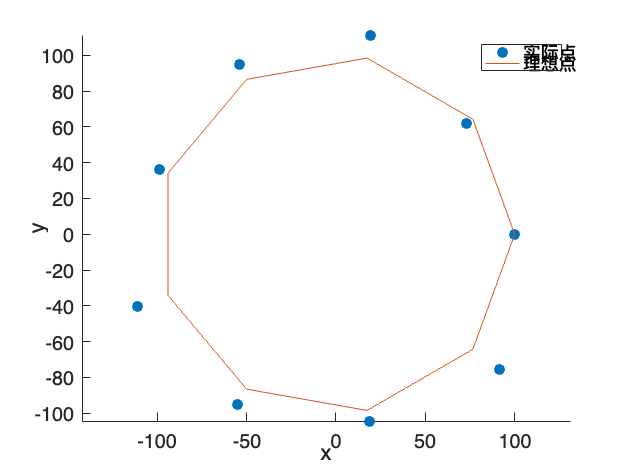


% 绘制最终位置
hold on
r = positions(:,1);
theta = positions(:,2);
axis equal
x0 = r .* cosd(theta);
y0 = r .* sind(theta);
scatter(x0, y0, 'filled');

% 绘制理想位置
R = 100;
theta_ideal = 0:2*pi/9:9;
x_ideal = R * cos(theta_ideal);
y_ideal = R * sin(theta_ideal);
plot(x_ideal, y_ideal)

xlabel("x");
ylabel("y")
legend(["实际点", "理想点"])